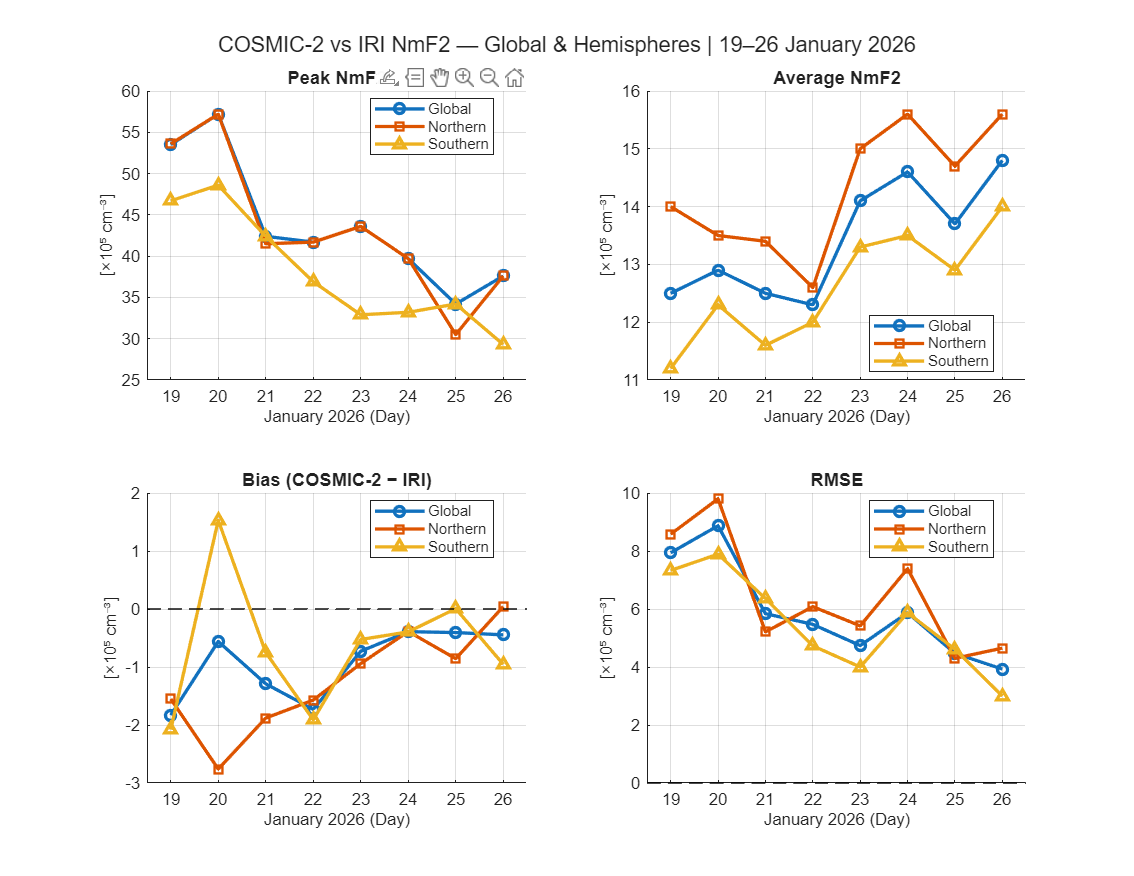

%% MULTI-DAY STATISTICS (you dont want to know how long this took me only to not use it :( )
days = [19,20, 21, 22, 23, 24, 25, 26];

% Global
peak_nmf2      = [53.5, 57.2, 42.4,  41.7,  43.6,  39.7,  34.2,  37.6];
avg_nmf2       = [12.5,12.9, 12.5,  12.3,  14.1,  14.6,  13.7,  14.8];
global_bias    = [-1.83,-0.560, -1.29, -1.73, -0.728,-0.391,-0.406,-0.446];
global_rmse    = [7.94,8.87,  5.84,  5.47,  4.74,  5.87,  4.47,  3.93];

%Northern Hemisphere
north_bias     = [-1.55,-2.76,-1.88, -1.57, -0.941,-0.387,-0.856, 0.041];
north_rmse     = [8.58,9.8, 5.21,  6.08,  5.42,  7.39,  4.30,  4.65];
north_peak     = [53.6,57.2, 41.5,  41.7,  43.6,  39.7,  30.5,  37.6];
north_avg      = [14.0, 13.5, 13.4,  12.6,  15.0,  15.6,  14.7,  15.6];

%Southern Hemisphere
south_bias     = [-2.08,1.53, -0.75, -1.91, -0.526,-0.394, 0.006,-0.954];
south_rmse     = [7.33,7.89, 6.36,  4.73,  4.00,  5.87,  4.61,  3.00];
south_peak     = [46.7,48.6, 42.4,  36.9,  32.9,  33.2,  34.2,  29.3];
south_avg      = [11.2,12.3, 11.6,  12.0,  13.3,  13.5,  12.9,  14.0];

% Longitude Band: -180 to -90
lon1_bias      = [0.713, 1.07, 3.04,  0.982, 0.384, 0.874,-1.22,  0.297];
lon1_rmse      = [10.5, 9.92, 5.65,  6.34,  5.54,  7.97,  4.32,  4.40];
lon1_peak      = [53.6,43.5, 42.4,  41.7,  43.6,  39.7,  31.3,  37.6];
lon1_avg       = [21.3,20.3, 22.7,  21.1,  21.2,  21.4,  19.8,  20.4];

% Longitude Band: -90 to 0
lon2_bias      = [-0.947,1.89, -2.65, -3.15, -1.46, -0.801, 0.553,-0.881];
lon2_rmse      = [7.76,12, 7.23,  6.15,  5.39,  5.96,  6.42,  3.43];
lon2_peak      = [44.5,57.2, 28.2,  30.5,  38.8,  33.2,  34.2,  25.4];
lon2_avg       = [16.0,19.1, 11.8,  13.9,  15.4,  15.9,  16.2,  14.7];

% Longitude Band: 0 to 90
lon3_bias      = [-5.36,-2.73, -2.65, -3.85, -2.37, -1.84, -1.73, -2.65];
lon3_rmse      = [6.0,3.6, 3.43,  4.31,  3.50,  2.62,  2.71,  3.22];
lon3_peak      = [8.82,14.4, 20.3,  10.5,  10.4,  19.5,  11.7,  13.2];
lon3_avg       = [2.34,5.08, 5.78,  3.50,  4.60,  5.90,  6.14,  5.97];

% Longitude Band: 90 to 180
lon4_bias      = [-3.13,-2.55, -1.03, -1.52, -0.194,-0.625, 1.04,  0.291];
lon4_rmse      = [5.08,7.48, 3.29,  4.29,  2.72,  3.00,  3.07,  3.82];
lon4_peak      = [28.0,17.3, 21.5,  33.9,  23.2,  21.9,  26.4,  28.9];
lon4_avg       = [6.09,6.18, 6.77,  7.59,  8.86,  9.62,  9.68, 11.0];
% Data plotting 


x      = days;
xtk    = days;
xlims  = [18.5 26.5];
xlab   = 'January 2026 (Day)';


lon1_rmse_plot    = lon1_rmse;
lon1_rmse_plot(1) = NaN;


figure('Color','white','Position',[100 100 1100 850])

hem_labels  = {'Global','Northern','Southern'};
hem_markers = {'-o','-s','-^'};
hem_lw      = [2, 2, 2];

hem_peak = [peak_nmf2; north_peak; south_peak];
hem_avg  = [avg_nmf2;  north_avg;  south_avg ];
hem_bias = [global_bias; north_bias; south_bias];
hem_rmse = [global_rmse; north_rmse; south_rmse];

hem_panels = {hem_peak, hem_avg, hem_bias, hem_rmse};
titles_hem = {'Peak NmF2','Average NmF2','Bias (COSMIC-2 − IRI)','RMSE'};

for p = 1:4
    subplot(2,2,p)
    hold on
    for r = 1:3
        plot(x, hem_panels{p}(r,:), hem_markers{r}, ...
             'LineWidth', hem_lw(r), 'DisplayName', hem_labels{r})
    end
    if p >= 3
        yline(0,'k--','LineWidth',1.2,'HandleVisibility','off')
    end
    xlabel(xlab,         'FontSize', 10)
    ylabel('[×10⁵ cm⁻³]','FontSize', 10)
    title(titles_hem{p}, 'FontSize', 11)
    xticks(xtk); xlim(xlims); grid on
    legend('Location','best','FontSize',9)
end
sgtitle('COSMIC-2 vs IRI NmF2 — Global & Hemispheres | 19–26 January 2026', ...
        'FontSize', 13)
exportgraphics(gcf,'multiday_global_hemispheres.png','Resolution',150)

fprintf('Global/hemisphere panel saved.\n')

Global/hemisphere panel saved.


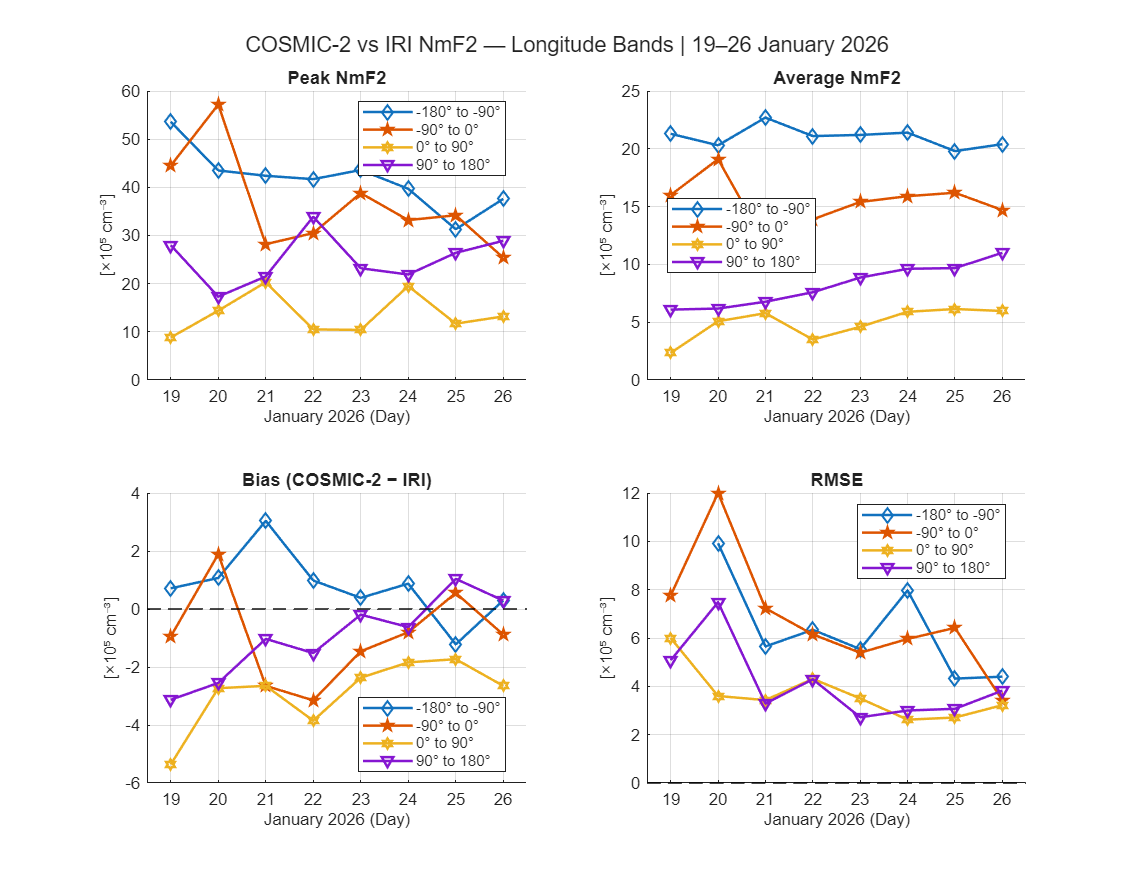



figure('Color','white','Position',[100 100 1100 850])

lon_labels  = {'-180° to -90°','-90° to 0°','0° to 90°','90° to 180°'};
lon_markers = {'-d','-p','-h','-v'};
lon_lw      = [1.5, 1.5, 1.5, 1.5];

lon_peak = [lon1_peak; lon2_peak; lon3_peak; lon4_peak];
lon_avg  = [lon1_avg;  lon2_avg;  lon3_avg;  lon4_avg ];
lon_bias = [lon1_bias; lon2_bias; lon3_bias; lon4_bias];
lon_rmse = [lon1_rmse_plot; lon2_rmse; lon3_rmse; lon4_rmse];

lon_panels = {lon_peak, lon_avg, lon_bias, lon_rmse};
titles_lon = {'Peak NmF2','Average NmF2','Bias (COSMIC-2 − IRI)','RMSE'};

for p = 1:4
    subplot(2,2,p)
    hold on
    for r = 1:4
        plot(x, lon_panels{p}(r,:), lon_markers{r}, ...
             'LineWidth', lon_lw(r), 'DisplayName', lon_labels{r})
    end
    if p >= 3
        yline(0,'k--','LineWidth',1.2,'HandleVisibility','off')
    end
    xlabel(xlab,         'FontSize', 10)
    ylabel('[×10⁵ cm⁻³]','FontSize', 10)
    title(titles_lon{p}, 'FontSize', 11)
    xticks(xtk); xlim(xlims); grid on
    legend('Location','best','FontSize',9)
end
sgtitle('COSMIC-2 vs IRI NmF2 — Longitude Bands | 19–26 January 2026', ...
        'FontSize', 13)
exportgraphics(gcf,'multiday_longitude_bands.png','Resolution',150)

fprintf('Longitude bands panel saved.\n')

Longitude bands panel saved.
